clear all
close all
clc

f = 60 % frequency

f = 60

w = 2*pi*f

w = 376.9911

Tcycle = 1/60

Tcycle = 0.0167

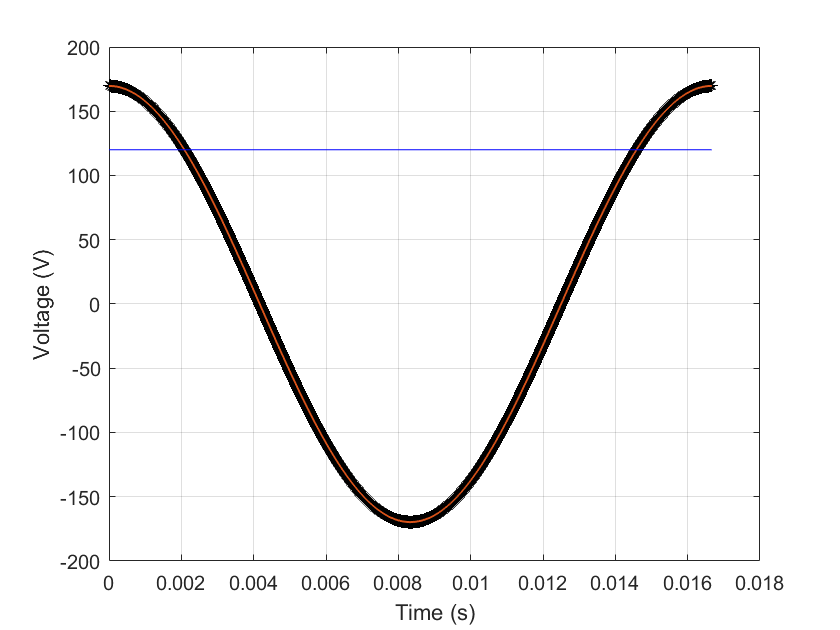

delta_T = 1/f/10000; %------a knob for tunning the time step
length_T = 1/f*1;
t = [0:delta_T:length_T]';

Va_rms = 120; %in volt
Va = Va_rms*sqrt(2)*cos(w*t + 0); % Using angle in radians is preferred
Va_dc = Va_rms*ones(length(t), 1);

figure(1)
plot(t,Va,'k--*')
hold on, grid on
stairs(t,Va,'LineWidth',1) 
xlabel('Time (s)'), ylabel('Voltage (V)')
plot(t, Va_dc, 'b')

Eac = 0;
R = 10;

for i = 1:1:length(t)
    Vac_t = abs(Va_rms*sqrt(2)*cos(w*t(i) + 0));
    Eac = Eac + Vac_t^2/R*delta_T;
end

Edc = Va_rms^2/R*length_T

Edc = 24

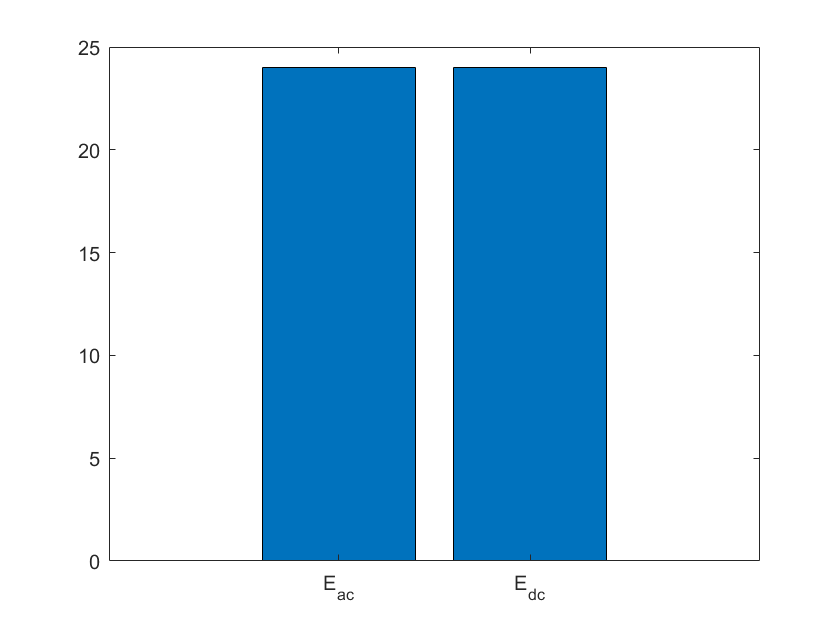


figure(2)
bar([1,2], [Eac Edc])
name =["E_{ac}";"E_{dc}"];
set(gca,'xticklabel',name)


Eerror = Eac - Edc

error = 0.0048